# Panda APF, EE-only, Map Column

clear

## Grid

grid = OctoGrid(2,2,2,100);

% add column
grid.addBox(1.25,0.9,0,0.2,0.2,1.5)

## Robot

% robot base transformation (move to x - 1m, y - 1m)
Tbase = eye(4);
Tbase(1:2,4) = [1 1]';

% set joints positions
joints = [0 0 0 0 0 0 0];

[robot_transforms] = GeometricPandaMATLAB(joints, Tbase);

## Show grid

% display
grid.showGridVol3D(grid.grid,'floor',true,'height',false)

ans = struct with fields:
      cdata: [200×200×200 double]
      alpha: []
      xdata: [0 200]
      ydata: [0 200]
      zdata: [0 200]
     parent: [1×1 Axes]
    handles: [1×600 Surface]
    texture: '3D'
        tag: 'vol3d_0fb407617143'


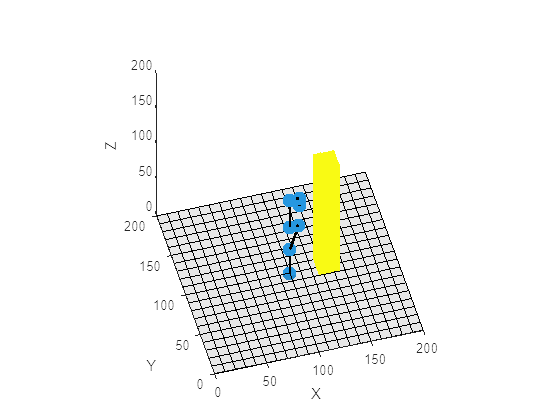

hold on
axis equal
showPanda(robot_transforms,grid.resolution)
hold off

## Generate goal points

% trajectory generation points (xyz position, xyz angles)
control_points = [1.088 1 0.926 0 0 0;
                  1.4 1.2 0.5 0 0 0]; 

## Calculate motion plan using kinematics, ignoring obstacles

% calculate list of joints positions using kinematics
[joints_positions_no_obstacles, EE_positions_no_obstacles, EE_distances, q_velocities] = kinematics_trajectory(control_points(2,:), Tbase, zeros(7,1));

## Display goal points

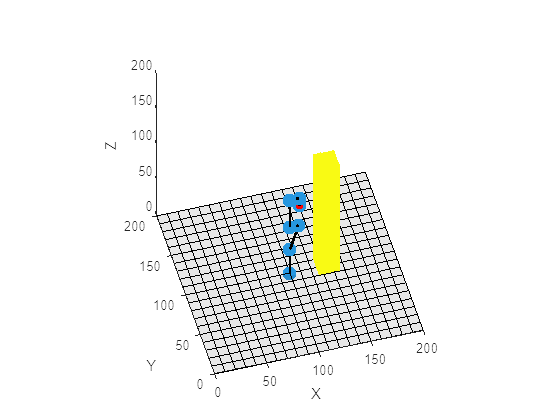

% Multiply the coordinates by 10 to scale the points
x = control_points(:, 1) * grid.resolution;
y = control_points(:, 2) * grid.resolution;
z = control_points(:, 3) * grid.resolution;

% display points
hold on

% Create a scatter plot with solid red points
scatter3(x, y, z, 'filled', 'MarkerFaceColor', 'red');

## Draw Calculated Poses

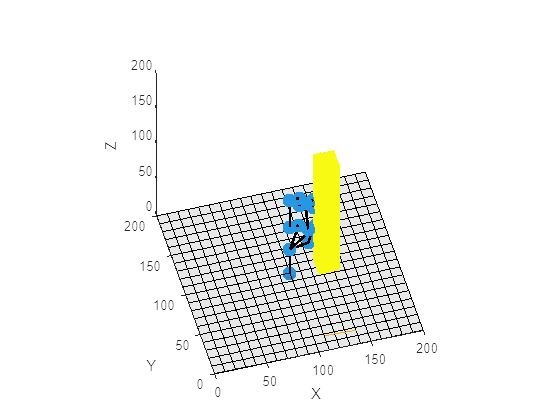

% draw calculated EE trajectory
% hold on
plot3(EE_positions_no_obstacles(1,:)* grid.resolution,EE_positions_no_obstacles(2,:)*10,EE_positions_no_obstacles(3,:)*10)

% draw initial pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_no_obstacles(:,1), Tbase);
showPanda(robot_transforms, grid.resolution)

% draw finish pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_no_obstacles(:,end), Tbase);
showPanda(robot_transforms, grid.resolution)

% draw mid pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_no_obstacles(:,ceil(length(joints_positions_no_obstacles)/6)), Tbase); % take pose after 1/6 steps ( poses get denser towards goal)
showPanda(robot_transforms,grid.resolution)

## Calculate attractive field

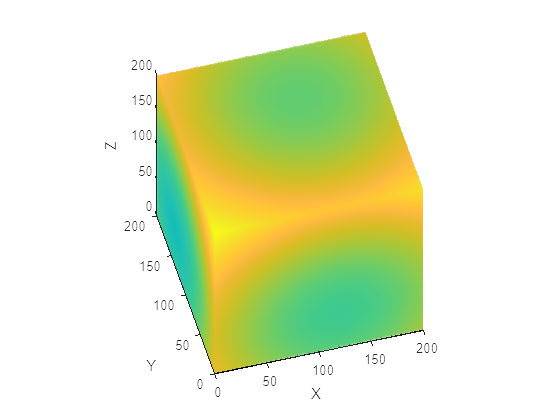

ans = struct with fields:
      cdata: [200×200×200 double]
      alpha: []
      xdata: [0 200]
      ydata: [0 200]
      zdata: [0 200]
     parent: [1×1 Axes]
    handles: [1×600 Surface]
    texture: '3D'
        tag: 'vol3d_f45ba5207217'


[grid_attractive] = attractive_field_3D(grid.grid, control_points(2,1:3), grid.resolution);
grid.showGridVol3D(grid_attractive)

## Calculate motion plan APF for EE only

Ka = 10; % attractive field coefficient
[joints_positions_APF_att, EE_positions_APF_att, goal_distances_APF_att, q_velocities_APF_att, ee_velocities_APF_att, values_APF_att] = EE_only_APF_trajectory(Ka * grid_attractive, grid.resolution, control_points(2,1:3), Tbase, zeros(7,1));

## Draw EE APF Calculated movement

figure

#### display grid

grid.showGridVol3D(grid.grid,'floor',true,'height',false)

ans = struct with fields:
      cdata: [200×200×200 double]
      alpha: []
      xdata: [0 200]
      ydata: [0 200]
      zdata: [0 200]
     parent: [1×1 Axes]
    handles: [1×600 Surface]
    texture: '3D'
        tag: 'vol3d_bfe8cb418f2a'


hold on
axis equal

#### draw calculated EE trajectory

hold on
plot3(EE_positions_no_obstacles(1,:)*grid.resolution,EE_positions_no_obstacles(2,:)*grid.resolution,EE_positions_no_obstacles(3,:)*grid.resolution)

#### draw calculated APF EE trajectory

hold on
plot3(EE_positions_APF_att(1,:)*grid.resolution,EE_positions_APF_att(2,:)*grid.resolution,EE_positions_APF_att(3,:)*grid.resolution)

#### draw a couple of robot poses

% draw initial pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_APF_att(:,1), Tbase);
showPanda(robot_transforms,grid.resolution)

% draw finish pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_APF_att(:,end), Tbase);
showPanda(robot_transforms,grid.resolution)

#### draw goal points

% Multiply the coordinates by 10 to scale the points
x = control_points(:, 1) * grid.resolution;
y = control_points(:, 2) * grid.resolution;
z = control_points(:, 3) * grid.resolution;

% display points
hold on

% Create a scatter plot with solid red points
scatter3(x, y, z, 'filled', 'MarkerFaceColor', 'red');

#### draw a number of interpolated APF vectors 

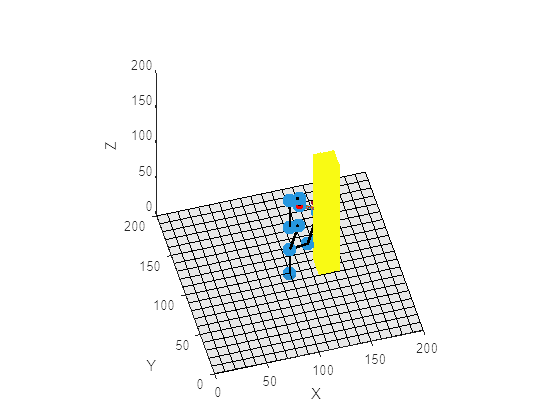

arrow_length = 100; % adjust the length to your preference

% multiple points
for i = 1:25:(length(EE_positions_APF_att)-1)
            % select point
            start_point = EE_positions_APF_att(:,i+1)'*grid.resolution;

            % calculate partial derivatives
            [dx] = ee_velocities_APF_att(1,i);
            [dy] = ee_velocities_APF_att(2,i);
            [dz] = ee_velocities_APF_att(3,i);

            % plot the arrow
            hold on
            quiver3(start_point(1), start_point(2), start_point(3), dx*arrow_length, dy*arrow_length, dz*arrow_length, 1, 'LineWidth', 2, 'MaxHeadSize', 1);
end

## Calculate obstacles repulsive field

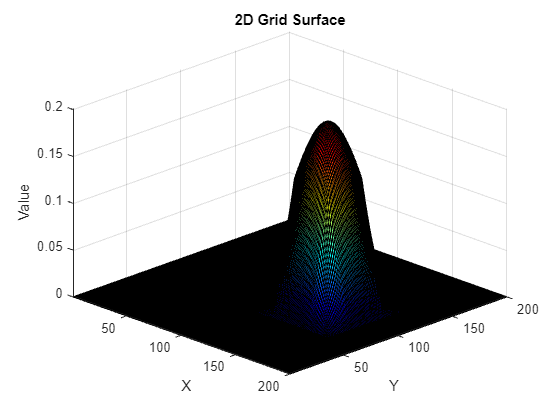

kernel_size = 50; % how far should obstacles exert effect
sigma = 25 ; % how quickly should effect exerted by obstacles fall

[grid_repulsive] = convolution_offline_3D(grid.grid,kernel_size,sigma);

figure()
grid.showSlice(grid_repulsive(:,:,50))

figure()
grid.showGridVol3D(grid_repulsive)

ans = struct with fields:
      cdata: [200×200×200 double]
      alpha: []
      xdata: [0 200]
      ydata: [0 200]
      zdata: [0 200]
     parent: [1×1 Axes]
    handles: [1×600 Surface]
    texture: '3D'
        tag: 'vol3d_a388632deb86'


hold on 
grid.showGridVol3D(grid.grid)

ans = struct with fields:
      cdata: [200×200×200 double]
      alpha: []
      xdata: [0 200]
      ydata: [0 200]
      zdata: [0 200]
     parent: [1×1 Axes]
    handles: [1×600 Surface]
    texture: '3D'
        tag: 'vol3d_14563429d112'


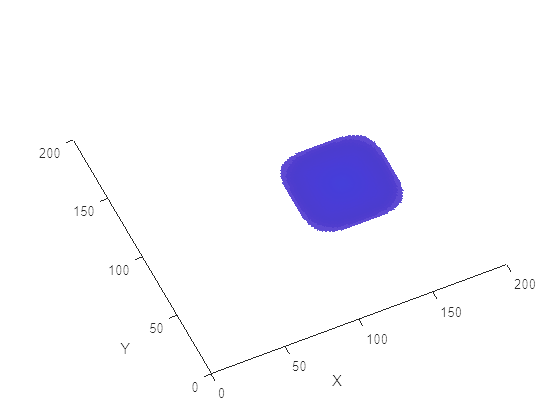

view([-25 90])

## Total field

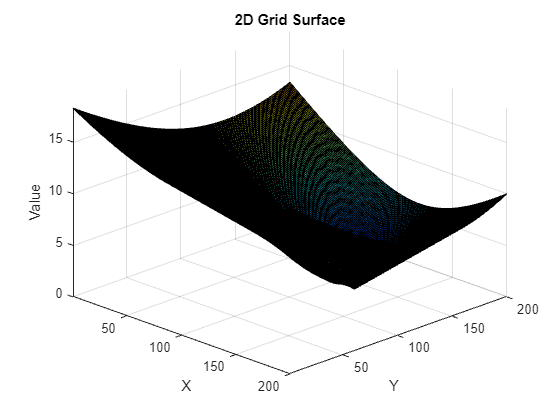

Ka = 10; % attractive field coefficient
Kr = -5; % repulsive field coefficient

% total field is a weighted sum of both
grid_total_field = Ka * grid_attractive + Kr * grid_repulsive;
figure()
grid.showSlice(grid_total_field(:,:,50))

## Calculate EE APF Attractive + Repulsive motion plan

[joints_positions_APF, EE_positions_APF, goal_distances_APF, q_velocities_APF, ee_velocities_APF, values_APF] = EE_only_APF_trajectory(grid_total_field, grid.resolution, control_points(2,1:3), Tbase, zeros(7,1),'mid_joints',true);

## Draw EE APF Calculated movement Att + Rep

figure

#### display grid

grid.showGridVol3D(grid.grid,'floor',false,'height',false)

ans = struct with fields:
      cdata: [200×200×200 double]
      alpha: []
      xdata: [0 200]
      ydata: [0 200]
      zdata: [0 200]
     parent: [1×1 Axes]
    handles: [1×600 Surface]
    texture: '3D'
        tag: 'vol3d_865a8e505fdf'


hold on
axis equal

#### draw calculated kinematics EE trajectory

hold on
plot3(EE_positions_no_obstacles(1,:)*grid.resolution,EE_positions_no_obstacles(2,:)*grid.resolution,EE_positions_no_obstacles(3,:)*grid.resolution)

#### draw calculated APF Attractive EE trajectory

hold on
plot3(EE_positions_APF_att(1,:)*grid.resolution,EE_positions_APF_att(2,:)*grid.resolution,EE_positions_APF_att(3,:)*grid.resolution)

#### draw calculated APF EE trajectory

plot3(EE_positions_APF(1,:)*grid.resolution,EE_positions_APF(2,:)*grid.resolution,EE_positions_APF(3,:)*grid.resolution,'green')

#### draw a couple of robot poses

% draw initial pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_APF(:,1), Tbase);
showPanda(robot_transforms,grid.resolution)

% draw finish pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_APF(:,end), Tbase);
showPanda(robot_transforms,grid.resolution)

#### draw goal points

% Multiply the coordinates by 10 to scale the points
x = control_points(:, 1) * grid.resolution;
y = control_points(:, 2) * grid.resolution;
z = control_points(:, 3) * grid.resolution;

% display points
hold on

% Create a scatter plot with solid red points
scatter3(x, y, z, 'filled', 'MarkerFaceColor', 'red');

#### draw a number of interpolated APF vectors

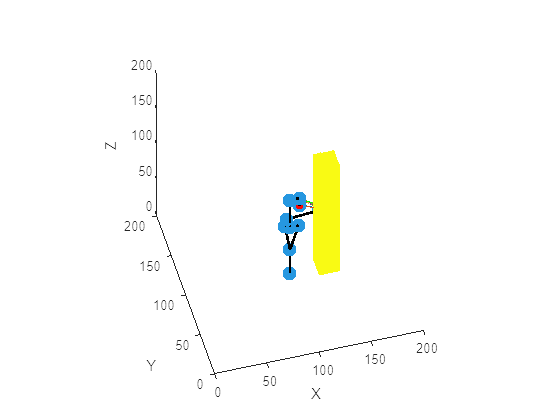

arrow_length = 100; % adjust the length to your preference

% multiple points
for i = 1:50:(length(EE_positions_APF)-1)
            % select point
            start_point = EE_positions_APF(:,i+1)'*grid.resolution;

            % calculate partial derivatives
            [dx] = ee_velocities_APF(1,i);
            [dy] = ee_velocities_APF(2,i);
            [dz] = ee_velocities_APF(3,i);

            % plot the arrow
            hold on
            quiver3(start_point(1), start_point(2), start_point(3), dx*arrow_length, dy*arrow_length, dz*arrow_length, 1, 'LineWidth', 2, 'MaxHeadSize', 1);
end